x=0:0.1:2*pi;
n=length(x);
y1=sin(x);
y2=cos(x);
figure;
col=rainbow(2);
plot(x,y1,"Color",col(1,:),"LineWidth",3);hold on
plot(x,y2,"Color",col(2,:),"LineWidth",3);
xticks([0,pi,2*pi]);
xticklabels({'0','\pi','2\pi'})
yticks([-1,0,1])
xlim([0,2*pi])
corr2(y1,y2)

ans = -2.2154e-04

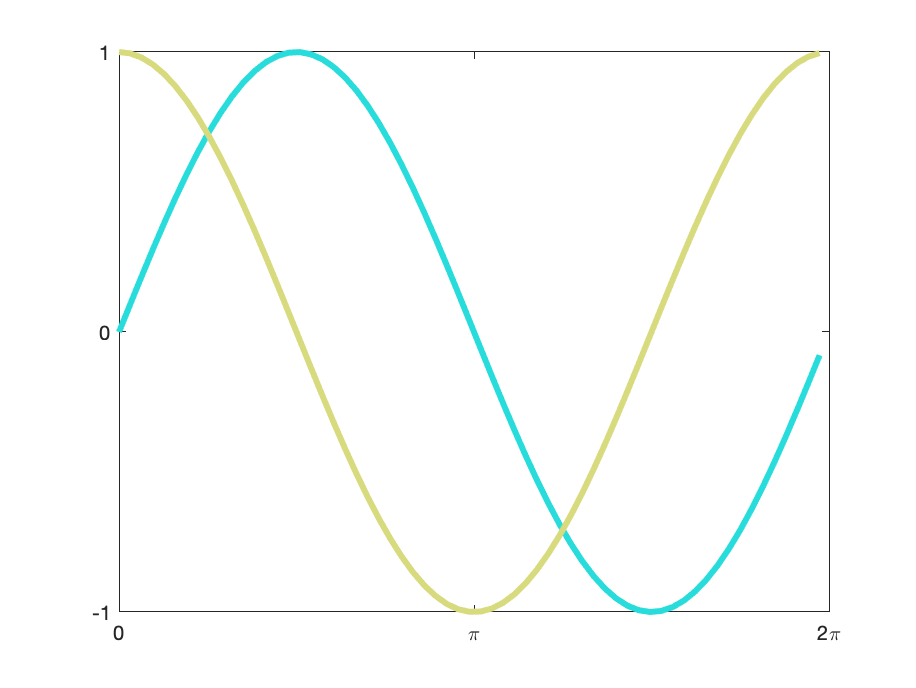

print('SinCos','-dpng');

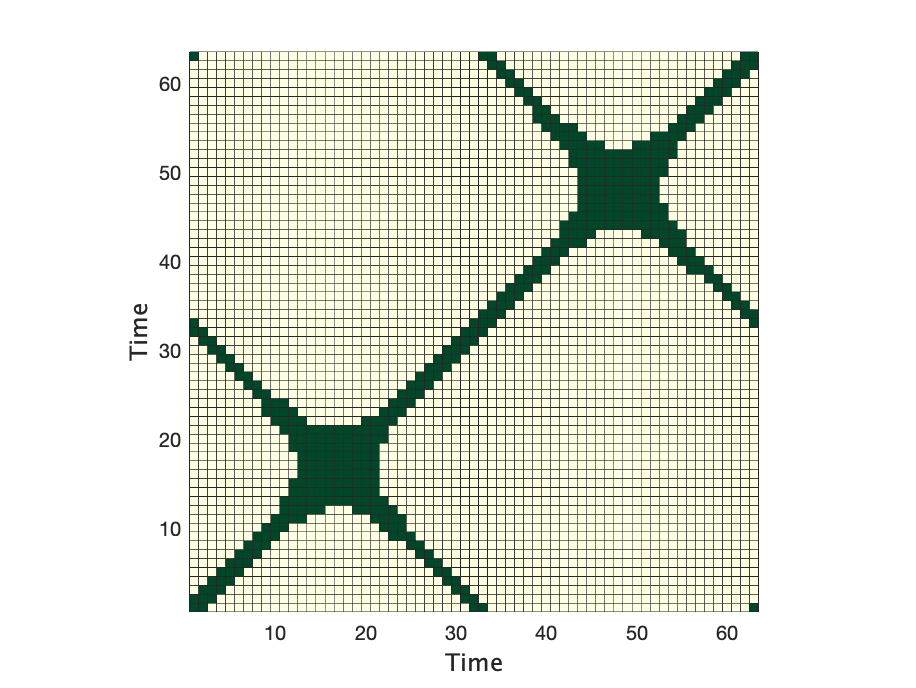


R1=zeros(n,n);
R2=zeros(n,n);
epsilon=0.1;
for i=1:n
    for j=1:n
        R1(i,j)=epsilon-abs(y1(i)-y1(j))>0;
    end
end
map=YlGn;
figure;
b=bar3(R1,1);
%hTitle=title('Recurrency plot');
hXLabel=xlabel('Time');
hYLabel=ylabel('Time');
for k=1:length(b)
    zdata=b(k).ZData;
    b(k).CData=zdata;
    b(k).FaceColor='interp';
end
colormap(map)
view(-90,90)
%colorbar
axis tight
set(gca,'FontName','Helvetica')
set([hXLabel,hYLabel],'FontName','AvantGarde')
set(gca,'FontSize',10)
set([hXLabel,hYLabel],'FontSize',12)
set(gcf,'Color',[1,1,1])
print('Reccurency_plot','-dpng');

function map = rainbow(N)

if nargin<1 || isempty(N)
	N = size(get(gcf,'colormap'),1);
else
	assert(isscalar(N)&&isreal(N),'First argument must be a real numeric scalar.')
end

C = [0.498039215686275,0,1;0.490196078431373,0.0117647058823529,0.996078431372549;0.486274509803922,0.0196078431372549,0.996078431372549;0.474509803921569,0.0352941176470588,0.996078431372549;0.466666666666667,0.0470588235294118,0.996078431372549;0.458823529411765,0.0588235294117647,0.996078431372549;0.450980392156863,0.0705882352941177,0.996078431372549;0.443137254901961,0.0823529411764706,0.996078431372549;0.435294117647059,0.0980392156862745,0.996078431372549;0.427450980392157,0.109803921568627,0.996078431372549;0.419607843137255,0.121568627450980,0.996078431372549;0.411764705882353,0.133333333333333,0.996078431372549;0.403921568627451,0.145098039215686,0.996078431372549;0.392156862745098,0.160784313725490,0.996078431372549;0.388235294117647,0.168627450980392,0.996078431372549;0.372549019607843,0.192156862745098,0.992156862745098;0.372549019607843,0.196078431372549,0.992156862745098;0.356862745098039,0.219607843137255,0.992156862745098;0.349019607843137,0.227450980392157,0.992156862745098;0.349019607843137,0.231372549019608,0.992156862745098;0.333333333333333,0.254901960784314,0.988235294117647;0.329411764705882,0.258823529411765,0.988235294117647;0.317647058823529,0.278431372549020,0.988235294117647;0.309803921568627,0.290196078431373,0.988235294117647;0.301960784313725,0.301960784313725,0.984313725490196;0.294117647058824,0.313725490196078,0.984313725490196;0.286274509803922,0.321568627450980,0.984313725490196;0.278431372549020,0.337254901960784,0.984313725490196;0.270588235294118,0.349019607843137,0.980392156862745;0.262745098039216,0.360784313725490,0.980392156862745;0.254901960784314,0.372549019607843,0.980392156862745;0.247058823529412,0.380392156862745,0.980392156862745;0.239215686274510,0.396078431372549,0.976470588235294;0.231372549019608,0.403921568627451,0.976470588235294;0.223529411764706,0.415686274509804,0.976470588235294;0.215686274509804,0.427450980392157,0.972549019607843;0.207843137254902,0.439215686274510,0.972549019607843;0.196078431372549,0.454901960784314,0.968627450980392;0.192156862745098,0.458823529411765,0.968627450980392;0.176470588235294,0.482352941176471,0.964705882352941;0.176470588235294,0.486274509803922,0.964705882352941;0.160784313725490,0.501960784313726,0.964705882352941;0.152941176470588,0.513725490196078,0.960784313725490;0.152941176470588,0.513725490196078,0.960784313725490;0.137254901960784,0.533333333333333,0.956862745098039;0.133333333333333,0.541176470588235,0.956862745098039;0.121568627450980,0.556862745098039,0.952941176470588;0.113725490196078,0.564705882352941,0.952941176470588;0.105882352941176,0.576470588235294,0.952941176470588;0.0980392156862745,0.584313725490196,0.949019607843137;0.0901960784313726,0.596078431372549,0.949019607843137;0.0823529411764706,0.603921568627451,0.945098039215686;0.0745098039215686,0.615686274509804,0.945098039215686;0.0666666666666667,0.623529411764706,0.941176470588235;0.0588235294117647,0.635294117647059,0.937254901960784;0.0509803921568627,0.643137254901961,0.937254901960784;0.0392156862745098,0.658823529411765,0.933333333333333;0.0352941176470588,0.662745098039216,0.933333333333333;0.0274509803921569,0.670588235294118,0.929411764705882;0.0196078431372549,0.682352941176471,0.929411764705882;0.0117647058823529,0.690196078431373,0.925490196078431;0,0.701960784313725,0.921568627450980;0,0.705882352941177,0.921568627450980;0.0156862745098039,0.725490196078431,0.917647058823529;0.0196078431372549,0.729411764705882,0.917647058823529;0.0313725490196078,0.741176470588235,0.909803921568627;0.0392156862745098,0.749019607843137,0.909803921568627;0.0392156862745098,0.749019607843137,0.909803921568627;0.0549019607843137,0.764705882352941,0.901960784313726;0.0588235294117647,0.768627450980392,0.901960784313726;0.0705882352941177,0.780392156862745,0.898039215686275;0.0784313725490196,0.788235294117647,0.894117647058824;0.0862745098039216,0.796078431372549,0.894117647058824;0.0941176470588235,0.803921568627451,0.890196078431373;0.101960784313725,0.811764705882353,0.886274509803922;0.109803921568627,0.819607843137255,0.886274509803922;0.117647058823529,0.823529411764706,0.882352941176471;0.125490196078431,0.831372549019608,0.878431372549020;0.133333333333333,0.839215686274510,0.874509803921569;0.141176470588235,0.843137254901961,0.874509803921569;0.152941176470588,0.854901960784314,0.870588235294118;0.156862745098039,0.858823529411765,0.866666666666667;0.164705882352941,0.862745098039216,0.862745098039216;0.172549019607843,0.870588235294118,0.862745098039216;0.180392156862745,0.874509803921569,0.858823529411765;0.192156862745098,0.886274509803922,0.850980392156863;0.196078431372549,0.886274509803922,0.850980392156863;0.211764705882353,0.898039215686275,0.843137254901961;0.215686274509804,0.898039215686275,0.843137254901961;0.227450980392157,0.909803921568627,0.839215686274510;0.235294117647059,0.913725490196078,0.835294117647059;0.235294117647059,0.913725490196078,0.835294117647059;0.250980392156863,0.925490196078431,0.827450980392157;0.258823529411765,0.929411764705882,0.823529411764706;0.266666666666667,0.933333333333333,0.819607843137255;0.274509803921569,0.937254901960784,0.819607843137255;0.282352941176471,0.941176470588235,0.815686274509804;0.290196078431373,0.945098039215686,0.811764705882353;0.298039215686275,0.949019607843137,0.807843137254902;0.305882352941177,0.952941176470588,0.803921568627451;0.313725490196078,0.956862745098039,0.800000000000000;0.321568627450980,0.960784313725490,0.796078431372549;0.329411764705882,0.964705882352941,0.792156862745098;0.337254901960784,0.964705882352941,0.788235294117647;0.349019607843137,0.972549019607843,0.780392156862745;0.352941176470588,0.972549019607843,0.780392156862745;0.368627450980392,0.976470588235294,0.772549019607843;0.368627450980392,0.976470588235294,0.772549019607843;0.376470588235294,0.980392156862745,0.768627450980392;0.392156862745098,0.984313725490196,0.760784313725490;0.392156862745098,0.984313725490196,0.760784313725490;0.407843137254902,0.988235294117647,0.752941176470588;0.411764705882353,0.988235294117647,0.749019607843137;0.423529411764706,0.992156862745098,0.745098039215686;0.431372549019608,0.992156862745098,0.741176470588235;0.431372549019608,0.992156862745098,0.741176470588235;0.447058823529412,0.996078431372549,0.733333333333333;0.454901960784314,0.996078431372549,0.729411764705882;0.462745098039216,0.996078431372549,0.725490196078431;0.470588235294118,0.996078431372549,0.721568627450980;0.478431372549020,0.996078431372549,0.717647058823529;0.486274509803922,0.996078431372549,0.709803921568628;0.494117647058824,0.996078431372549,0.705882352941177;0.501960784313726,0.996078431372549,0.701960784313725;0.509803921568627,0.996078431372549,0.698039215686275;0.517647058823530,0.996078431372549,0.694117647058824;0.525490196078431,0.996078431372549,0.690196078431373;0.533333333333333,0.996078431372549,0.686274509803922;0.545098039215686,0.996078431372549,0.678431372549020;0.549019607843137,0.996078431372549,0.674509803921569;0.564705882352941,0.992156862745098,0.666666666666667;0.568627450980392,0.992156862745098,0.666666666666667;0.572549019607843,0.992156862745098,0.662745098039216;0.588235294117647,0.988235294117647,0.654901960784314;0.588235294117647,0.988235294117647,0.654901960784314;0.603921568627451,0.984313725490196,0.643137254901961;0.607843137254902,0.980392156862745,0.639215686274510;0.619607843137255,0.980392156862745,0.635294117647059;0.627450980392157,0.976470588235294,0.631372549019608;0.635294117647059,0.976470588235294,0.623529411764706;0.643137254901961,0.972549019607843,0.619607843137255;0.650980392156863,0.968627450980392,0.615686274509804;0.658823529411765,0.964705882352941,0.611764705882353;0.666666666666667,0.964705882352941,0.603921568627451;0.674509803921569,0.960784313725490,0.600000000000000;0.682352941176471,0.956862745098039,0.596078431372549;0.690196078431373,0.952941176470588,0.592156862745098;0.698039215686275,0.949019607843137,0.584313725490196;0.705882352941177,0.945098039215686,0.580392156862745;0.713725490196078,0.941176470588235,0.576470588235294;0.721568627450980,0.937254901960784,0.572549019607843;0.729411764705882,0.933333333333333,0.564705882352941;0.741176470588235,0.925490196078431,0.556862745098039;0.745098039215686,0.925490196078431,0.556862745098039;0.760784313725490,0.913725490196078,0.545098039215686;0.764705882352941,0.913725490196078,0.545098039215686;0.768627450980392,0.909803921568627,0.541176470588235;0.784313725490196,0.898039215686275,0.529411764705882;0.784313725490196,0.898039215686275,0.529411764705882;0.800000000000000,0.886274509803922,0.517647058823530;0.803921568627451,0.882352941176471,0.513725490196078;0.815686274509804,0.874509803921569,0.509803921568627;0.823529411764706,0.870588235294118,0.501960784313726;0.831372549019608,0.862745098039216,0.498039215686275;0.839215686274510,0.858823529411765,0.494117647058824;0.847058823529412,0.850980392156863,0.486274509803922;0.854901960784314,0.843137254901961,0.482352941176471;0.862745098039216,0.839215686274510,0.478431372549020;0.870588235294118,0.831372549019608,0.470588235294118;0.878431372549020,0.823529411764706,0.466666666666667;0.886274509803922,0.819607843137255,0.458823529411765;0.894117647058824,0.811764705882353,0.454901960784314;0.901960784313726,0.803921568627451,0.450980392156863;0.909803921568627,0.796078431372549,0.443137254901961;0.917647058823529,0.788235294117647,0.439215686274510;0.925490196078431,0.780392156862745,0.431372549019608;0.941176470588235,0.764705882352941,0.423529411764706;0.941176470588235,0.764705882352941,0.423529411764706;0.956862745098039,0.749019607843137,0.411764705882353;0.960784313725490,0.745098039215686,0.407843137254902;0.964705882352941,0.741176470588235,0.403921568627451;0.980392156862745,0.725490196078431,0.392156862745098;0.980392156862745,0.725490196078431,0.392156862745098;0.996078431372549,0.705882352941177,0.380392156862745;1,0.698039215686275,0.376470588235294;1,0.690196078431373,0.372549019607843;1,0.682352941176471,0.364705882352941;1,0.670588235294118,0.360784313725490;1,0.662745098039216,0.352941176470588;1,0.654901960784314,0.349019607843137;1,0.643137254901961,0.341176470588235;1,0.635294117647059,0.337254901960784;1,0.623529411764706,0.329411764705882;1,0.615686274509804,0.325490196078431;1,0.603921568627451,0.317647058823529;1,0.588235294117647,0.309803921568627;1,0.584313725490196,0.305882352941177;1,0.576470588235294,0.301960784313725;1,0.560784313725490,0.294117647058824;1,0.556862745098039,0.290196078431373;1,0.533333333333333,0.278431372549020;1,0.533333333333333,0.278431372549020;1,0.513725490196078,0.266666666666667;1,0.505882352941176,0.262745098039216;1,0.501960784313726,0.258823529411765;1,0.482352941176471,0.247058823529412;1,0.478431372549020,0.247058823529412;1,0.458823529411765,0.235294117647059;1,0.450980392156863,0.231372549019608;1,0.439215686274510,0.223529411764706;1,0.427450980392157,0.219607843137255;1,0.415686274509804,0.211764705882353;1,0.403921568627451,0.207843137254902;1,0.392156862745098,0.200000000000000;1,0.380392156862745,0.192156862745098;1,0.372549019607843,0.188235294117647;1,0.360784313725490,0.180392156862745;1,0.349019607843137,0.176470588235294;1,0.337254901960784,0.168627450980392;1,0.317647058823529,0.160784313725490;1,0.313725490196078,0.156862745098039;1,0.301960784313725,0.152941176470588;1,0.286274509803922,0.145098039215686;1,0.278431372549020,0.141176470588235;1,0.254901960784314,0.125490196078431;1,0.254901960784314,0.125490196078431;1,0.231372549019608,0.113725490196078;1,0.223529411764706,0.109803921568627;1,0.219607843137255,0.109803921568627;1,0.192156862745098,0.0980392156862745;1,0.188235294117647,0.0941176470588235;1,0.168627450980392,0.0823529411764706;1,0.156862745098039,0.0784313725490196;1,0.145098039215686,0.0705882352941177;1,0.133333333333333,0.0666666666666667;1,0.121568627450980,0.0588235294117647;1,0.109803921568627,0.0549019607843137;1,0.0980392156862745,0.0470588235294118;1,0.0823529411764706,0.0392156862745098;1,0.0705882352941177,0.0352941176470588;1,0.0588235294117647,0.0274509803921569;1,0.0470588235294118,0.0235294117647059;1,0.0352941176470588,0.0156862745098039;1,0.0156862745098039,0.00392156862745098;1,0.0117647058823529,0.00392156862745098;1,0,0;1,0,0];

num = size(C,1);
vec = linspace(0,num+1,N+2);
map = interp1(1:num,C,vec(2:end-1),'linear','extrap'); %...插值
map = max(0,min(1,map));
end

function map = YlGn(N)

if nargin<1 || isempty(N)
	N = size(get(gcf,'colormap'),1);
else
	assert(isscalar(N)&&isreal(N),'First argument must be a real numeric scalar.')
end

C = [0.996078431372549,0.996078431372549,0.890196078431373;0.996078431372549,0.996078431372549,0.886274509803922;0.996078431372549,0.996078431372549,0.878431372549020;0.992156862745098,0.996078431372549,0.870588235294118;0.992156862745098,0.996078431372549,0.870588235294118;0.992156862745098,0.996078431372549,0.858823529411765;0.988235294117647,0.996078431372549,0.854901960784314;0.988235294117647,0.996078431372549,0.847058823529412;0.988235294117647,0.996078431372549,0.843137254901961;0.988235294117647,0.996078431372549,0.839215686274510;0.984313725490196,0.992156862745098,0.831372549019608;0.984313725490196,0.992156862745098,0.827450980392157;0.984313725490196,0.992156862745098,0.819607843137255;0.984313725490196,0.992156862745098,0.815686274509804;0.980392156862745,0.992156862745098,0.807843137254902;0.980392156862745,0.992156862745098,0.803921568627451;0.980392156862745,0.992156862745098,0.800000000000000;0.980392156862745,0.992156862745098,0.792156862745098;0.976470588235294,0.992156862745098,0.788235294117647;0.976470588235294,0.992156862745098,0.784313725490196;0.976470588235294,0.988235294117647,0.776470588235294;0.976470588235294,0.988235294117647,0.772549019607843;0.972549019607843,0.988235294117647,0.760784313725490;0.972549019607843,0.988235294117647,0.760784313725490;0.972549019607843,0.988235294117647,0.756862745098039;0.972549019607843,0.988235294117647,0.749019607843137;0.968627450980392,0.988235294117647,0.745098039215686;0.968627450980392,0.988235294117647,0.733333333333333;0.968627450980392,0.988235294117647,0.733333333333333;0.964705882352941,0.984313725490196,0.721568627450980;0.960784313725490,0.984313725490196,0.721568627450980;0.960784313725490,0.984313725490196,0.717647058823529;0.956862745098039,0.980392156862745,0.713725490196078;0.956862745098039,0.980392156862745,0.713725490196078;0.949019607843137,0.980392156862745,0.709803921568628;0.945098039215686,0.976470588235294,0.705882352941177;0.941176470588235,0.976470588235294,0.705882352941177;0.937254901960784,0.972549019607843,0.701960784313725;0.933333333333333,0.972549019607843,0.698039215686275;0.929411764705882,0.972549019607843,0.698039215686275;0.925490196078431,0.968627450980392,0.694117647058824;0.921568627450980,0.968627450980392,0.690196078431373;0.917647058823529,0.968627450980392,0.686274509803922;0.913725490196078,0.964705882352941,0.686274509803922;0.909803921568627,0.964705882352941,0.682352941176471;0.905882352941177,0.960784313725490,0.678431372549020;0.898039215686275,0.960784313725490,0.674509803921569;0.898039215686275,0.960784313725490,0.674509803921569;0.898039215686275,0.956862745098039,0.670588235294118;0.894117647058824,0.956862745098039,0.670588235294118;0.890196078431373,0.956862745098039,0.666666666666667;0.882352941176471,0.952941176470588,0.662745098039216;0.882352941176471,0.952941176470588,0.662745098039216;0.874509803921569,0.949019607843137,0.654901960784314;0.870588235294118,0.949019607843137,0.650980392156863;0.866666666666667,0.945098039215686,0.650980392156863;0.862745098039216,0.945098039215686,0.647058823529412;0.862745098039216,0.945098039215686,0.647058823529412;0.854901960784314,0.941176470588235,0.643137254901961;0.850980392156863,0.941176470588235,0.639215686274510;0.847058823529412,0.937254901960784,0.635294117647059;0.843137254901961,0.937254901960784,0.635294117647059;0.835294117647059,0.933333333333333,0.631372549019608;0.831372549019608,0.933333333333333,0.627450980392157;0.827450980392157,0.929411764705882,0.627450980392157;0.819607843137255,0.925490196078431,0.623529411764706;0.815686274509804,0.925490196078431,0.619607843137255;0.807843137254902,0.921568627450980,0.619607843137255;0.803921568627451,0.921568627450980,0.615686274509804;0.800000000000000,0.917647058823529,0.611764705882353;0.788235294117647,0.913725490196078,0.607843137254902;0.788235294117647,0.913725490196078,0.607843137254902;0.776470588235294,0.909803921568627,0.603921568627451;0.772549019607843,0.905882352941177,0.600000000000000;0.772549019607843,0.905882352941177,0.600000000000000;0.760784313725490,0.901960784313726,0.596078431372549;0.760784313725490,0.901960784313726,0.596078431372549;0.749019607843137,0.898039215686275,0.588235294117647;0.745098039215686,0.894117647058824,0.588235294117647;0.741176470588235,0.890196078431373,0.584313725490196;0.733333333333333,0.890196078431373,0.584313725490196;0.729411764705882,0.886274509803922,0.580392156862745;0.721568627450980,0.886274509803922,0.576470588235294;0.717647058823529,0.882352941176471,0.576470588235294;0.713725490196078,0.878431372549020,0.572549019607843;0.705882352941177,0.878431372549020,0.568627450980392;0.701960784313725,0.874509803921569,0.568627450980392;0.698039215686275,0.874509803921569,0.564705882352941;0.690196078431373,0.870588235294118,0.560784313725490;0.686274509803922,0.866666666666667,0.560784313725490;0.678431372549020,0.866666666666667,0.556862745098039;0.674509803921569,0.862745098039216,0.552941176470588;0.666666666666667,0.862745098039216,0.552941176470588;0.662745098039216,0.858823529411765,0.549019607843137;0.647058823529412,0.850980392156863,0.545098039215686;0.647058823529412,0.850980392156863,0.545098039215686;0.635294117647059,0.847058823529412,0.537254901960784;0.631372549019608,0.843137254901961,0.537254901960784;0.627450980392157,0.843137254901961,0.537254901960784;0.615686274509804,0.839215686274510,0.529411764705882;0.611764705882353,0.839215686274510,0.529411764705882;0.603921568627451,0.831372549019608,0.525490196078431;0.596078431372549,0.831372549019608,0.521568627450980;0.588235294117647,0.827450980392157,0.521568627450980;0.584313725490196,0.823529411764706,0.517647058823530;0.576470588235294,0.819607843137255,0.513725490196078;0.568627450980392,0.819607843137255,0.513725490196078;0.564705882352941,0.815686274509804,0.509803921568627;0.556862745098039,0.811764705882353,0.505882352941176;0.549019607843137,0.811764705882353,0.505882352941176;0.545098039215686,0.807843137254902,0.501960784313726;0.537254901960784,0.803921568627451,0.498039215686275;0.529411764705882,0.800000000000000,0.498039215686275;0.525490196078431,0.800000000000000,0.494117647058824;0.517647058823530,0.796078431372549,0.490196078431373;0.509803921568627,0.792156862745098,0.490196078431373;0.501960784313726,0.788235294117647,0.486274509803922;0.498039215686275,0.788235294117647,0.482352941176471;0.486274509803922,0.780392156862745,0.478431372549020;0.486274509803922,0.780392156862745,0.478431372549020;0.470588235294118,0.776470588235294,0.474509803921569;0.466666666666667,0.772549019607843,0.470588235294118;0.466666666666667,0.772549019607843,0.470588235294118;0.450980392156863,0.764705882352941,0.462745098039216;0.447058823529412,0.764705882352941,0.462745098039216;0.439215686274510,0.760784313725490,0.458823529411765;0.431372549019608,0.756862745098039,0.454901960784314;0.423529411764706,0.752941176470588,0.450980392156863;0.419607843137255,0.749019607843137,0.447058823529412;0.411764705882353,0.745098039215686,0.443137254901961;0.403921568627451,0.741176470588235,0.439215686274510;0.396078431372549,0.741176470588235,0.435294117647059;0.392156862745098,0.737254901960784,0.431372549019608;0.384313725490196,0.733333333333333,0.431372549019608;0.376470588235294,0.729411764705882,0.427450980392157;0.368627450980392,0.725490196078431,0.423529411764706;0.364705882352941,0.721568627450980,0.419607843137255;0.349019607843137,0.717647058823529,0.411764705882353;0.349019607843137,0.717647058823529,0.411764705882353;0.345098039215686,0.713725490196078,0.407843137254902;0.333333333333333,0.705882352941177,0.400000000000000;0.329411764705882,0.705882352941177,0.400000000000000;0.317647058823529,0.698039215686275,0.396078431372549;0.317647058823529,0.698039215686275,0.396078431372549;0.301960784313725,0.694117647058824,0.388235294117647;0.294117647058824,0.690196078431373,0.384313725490196;0.294117647058824,0.690196078431373,0.384313725490196;0.282352941176471,0.682352941176471,0.376470588235294;0.278431372549020,0.678431372549020,0.372549019607843;0.270588235294118,0.678431372549020,0.372549019607843;0.262745098039216,0.674509803921569,0.368627450980392;0.254901960784314,0.670588235294118,0.364705882352941;0.250980392156863,0.666666666666667,0.360784313725490;0.247058823529412,0.662745098039216,0.356862745098039;0.243137254901961,0.654901960784314,0.352941176470588;0.239215686274510,0.650980392156863,0.352941176470588;0.235294117647059,0.647058823529412,0.349019607843137;0.231372549019608,0.643137254901961,0.345098039215686;0.227450980392157,0.635294117647059,0.341176470588235;0.223529411764706,0.631372549019608,0.337254901960784;0.219607843137255,0.627450980392157,0.333333333333333;0.215686274509804,0.619607843137255,0.329411764705882;0.215686274509804,0.619607843137255,0.329411764705882;0.211764705882353,0.611764705882353,0.325490196078431;0.203921568627451,0.603921568627451,0.317647058823529;0.203921568627451,0.603921568627451,0.317647058823529;0.196078431372549,0.592156862745098,0.313725490196078;0.196078431372549,0.592156862745098,0.313725490196078;0.188235294117647,0.584313725490196,0.305882352941177;0.184313725490196,0.580392156862745,0.301960784313725;0.184313725490196,0.580392156862745,0.301960784313725;0.176470588235294,0.568627450980392,0.298039215686275;0.172549019607843,0.564705882352941,0.294117647058824;0.168627450980392,0.560784313725490,0.290196078431373;0.164705882352941,0.556862745098039,0.286274509803922;0.160784313725490,0.549019607843137,0.282352941176471;0.156862745098039,0.545098039215686,0.282352941176471;0.152941176470588,0.541176470588235,0.278431372549020;0.152941176470588,0.537254901960784,0.274509803921569;0.149019607843137,0.529411764705882,0.270588235294118;0.145098039215686,0.525490196078431,0.266666666666667;0.141176470588235,0.521568627450980,0.266666666666667;0.137254901960784,0.517647058823530,0.262745098039216;0.133333333333333,0.513725490196078,0.258823529411765;0.129411764705882,0.509803921568627,0.258823529411765;0.117647058823529,0.501960784313726,0.254901960784314;0.117647058823529,0.501960784313726,0.254901960784314;0.113725490196078,0.498039215686275,0.254901960784314;0.105882352941176,0.494117647058824,0.250980392156863;0.105882352941176,0.494117647058824,0.250980392156863;0.0980392156862745,0.486274509803922,0.247058823529412;0.0980392156862745,0.486274509803922,0.247058823529412;0.0901960784313726,0.478431372549020,0.243137254901961;0.0862745098039216,0.474509803921569,0.243137254901961;0.0823529411764706,0.470588235294118,0.243137254901961;0.0745098039215686,0.466666666666667,0.239215686274510;0.0705882352941177,0.466666666666667,0.239215686274510;0.0666666666666667,0.462745098039216,0.239215686274510;0.0627450980392157,0.458823529411765,0.235294117647059;0.0588235294117647,0.454901960784314,0.235294117647059;0.0549019607843137,0.450980392156863,0.231372549019608;0.0509803921568627,0.447058823529412,0.231372549019608;0.0470588235294118,0.443137254901961,0.231372549019608;0.0431372549019608,0.439215686274510,0.227450980392157;0.0392156862745098,0.439215686274510,0.227450980392157;0.0313725490196078,0.435294117647059,0.227450980392157;0.0274509803921569,0.431372549019608,0.223529411764706;0.0235294117647059,0.427450980392157,0.223529411764706;0.0196078431372549,0.423529411764706,0.219607843137255;0.0117647058823529,0.415686274509804,0.219607843137255;0.0117647058823529,0.415686274509804,0.219607843137255;0.00784313725490196,0.411764705882353,0.215686274509804;0,0.407843137254902,0.215686274509804;0,0.407843137254902,0.215686274509804;0,0.396078431372549,0.211764705882353;0,0.392156862745098,0.207843137254902;0,0.388235294117647,0.207843137254902;0,0.384313725490196,0.203921568627451;0,0.380392156862745,0.203921568627451;0,0.376470588235294,0.200000000000000;0,0.372549019607843,0.200000000000000;0,0.368627450980392,0.200000000000000;0,0.364705882352941,0.196078431372549;0,0.360784313725490,0.196078431372549;0,0.352941176470588,0.192156862745098;0,0.349019607843137,0.192156862745098;0,0.345098039215686,0.188235294117647;0,0.341176470588235,0.188235294117647;0,0.337254901960784,0.188235294117647;0,0.333333333333333,0.184313725490196;0,0.329411764705882,0.184313725490196;0,0.321568627450980,0.180392156862745;0,0.321568627450980,0.180392156862745;0,0.309803921568627,0.176470588235294;0,0.309803921568627,0.176470588235294;0,0.305882352941177,0.172549019607843;0,0.298039215686275,0.172549019607843;0,0.298039215686275,0.172549019607843;0,0.290196078431373,0.168627450980392;0,0.286274509803922,0.164705882352941;0,0.282352941176471,0.164705882352941;0,0.278431372549020,0.160784313725490;0,0.274509803921569,0.160784313725490;0,0.274509803921569,0.160784313725490];

num = size(C,1);
vec = linspace(0,num+1,N+2);
map = interp1(1:num,C,vec(2:end-1),'linear','extrap'); %...插值
map = max(0,min(1,map));
end